addpath("Functions\")
[A,B,C,D] = systemDynamics;
N = 3;

## ***Choose a controller type***

%ContrStruct = ones(N,N); %centralized controller
%ContrStruct = diag(ones(N,1)); %decentralized controller
%Distribuited controller
     ContrStruct =[1,1,0;
         0,1,1;
1,0,1];
%H2 controller (LQG Based)
% control effort

## *Choose a value of alpha for the fast controller in CT*

alpha_fast_CT = 1.0413; %computed before, check for it later in slow_eig_CT
%alpha_fast_CT = 10 %alpha (remember that it's the module)

## *Choose the initial conditions for the sampling time (consistent with the one in open loop)*

x0 = [-1,0,1,0,-1,0];
[F,G,H,L,h,dominantFrequency] = discretize(x0(1),x0(3),x0(5));

*COMPUTATION OF THE GAIN MATRICIES*

[K_stab_CT,K_stab_DT,K_fast_CT,K_cyrcle_DT] = LMI_gains(ContrStruct,alpha_fast_CT,x0(1),x0(2),x0(3));


 num. of constraints = 21
 dim. of sdp    var  = 12,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.4e+01|3.4e+01|1.2e+03|-1.200000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.863|1.000|1.3e+01|1.0e-01|1.4e+02|-3.723961e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.987|1.000|1.7e-01|1.0e-02|1.8e+00|-4.827803e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|1.9e-03|1.0e-03|2.0e-02|-5.358834e-05  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|2.0e-05|4.7e-04|2.2e-04|-5.894506e-07  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|2.2e-07|1.4e-05|2.5e-06|-6.480528e-09  0.000000e+00| 0:

K_stab_CT =    -2.5437    0.9696    1.8083   -0.1171         0         0
         0         0 -118.6874  -36.8468   13.0787    9.2098
    1.7771   -0.6038         0         0    8.3064    3.7077


rho = -0.4266

feas = 0


 num. of constraints = 21
 dim. of sdp    var  = 12,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.4e+01|3.4e+01|1.2e+03|-1.200000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.844|0.962|1.5e+01|1.4e+00|1.5e+02|-5.180882e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.950|1.000|7.3e-01|1.0e-02|7.5e+00|-3.321442e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|8.4e-03|1.0e-03|8.6e-02|-3.801004e-04  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|9.2e-05|1.8e-03|9.5e-04|-4.183680e-06  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|1.0e-06|2.8e-05|1.0e-05|-4.609014e-08  0.000000e+00| 0:

K_fast_CT =     5.0181    4.7464    0.8957   -0.3673         0         0
         0         0 -444.4423 -131.8548   72.7770   24.8687
   -0.1528   -1.2866         0         0   41.4372   13.3826


rho_fast = -2.3163

feas = 0

Constraints:
    {1×1 lmi}


 num. of constraints = 21
 dim. of sdp    var  = 12,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|3.4e+01|1.4e+03|-1.411953e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.833|0.948|4.9e+00|1.8e+00|1.9e+02|-6.255547e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.867|1.000|6.5e-01|1.0e-02|2.8e+01|-1.194023e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|7.9e-03|1.0e-03|3.4e-01|-1.451013e-03  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|8.7e-05|1.7e-03|3.7e-03|-1.598473e-05  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|9.5e-07|2.7e-05|4.1e-05|-1.

K_stab_DT =    -1.6254    3.5520    1.6674    0.0209         0         0
         0         0  -21.7763  -37.2996   -0.8029    2.4129
    1.7669   -0.0735         0         0   -0.8824    3.7040


rho = 0.9524

feas = 0


 num. of constraints = 21
 dim. of sdp    var  = 12,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.6e+01|3.4e+01|1.4e+03|-1.411953e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.881|0.919|1.9e+00|2.8e+00|1.4e+02|-9.674520e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.869|0.955|2.5e-01|1.4e-01|1.4e+01|-7.534716e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.872|1.000|3.2e-02|1.0e-03|1.8e+00|-2.496102e-01  0.000000e+00| 0:0:00| chol  1  1 
 4|0.987|1.000|4.0e-04|6.4e-03|2.3e-02|-3.122111e-03  0.000000e+00| 0:0:00| chol  1  1 
 5|0.985|1.000|6.2e-06|8.9e-05|3.5e-04|-4.744993e-05  0.000000e+00| 0:

K_fast_DT =    35.3694   10.6831    4.6572    0.4420         0         0
         0         0 -370.0996 -105.2570   -0.8267    0.8059
    6.1745    0.5957         0         0   33.8895   10.4993


rho_cyrcle_DT = 0.4907

feas = 0

* CONTINOUS TIME EIGENVALUES*

eig_CT=eig(A+B*K_stab_CT)

eig_CT =   -0.4266 + 1.0876i
  -0.4266 - 1.0876i
  -2.1652 + 3.2720i
  -2.1652 - 3.2720i
  -1.5892 + 2.7214i
  -1.5892 - 2.7214i


By using a state feedback control law with gain matrix K_stab_CT we're indeed able to stabilize the system.

Considering the eigenvalue having negagtive real value closer to the origin (biggest real part) we're selecting the one assiging the time response of the system.

slow_eig_CT = abs(max(real(eig_CT)))

slow_eig_CT = 0.4266

We can compute an LMI that keeps the system stability but at the same time guarantees all the eigenvalues to have real part smaller (so on the left) of slow_eig_CT (or in general any parameter alpha).

eig_fast_CT = eig(A+B*K_fast_CT)

eig_fast_CT =   -2.3163 + 1.8184i
  -2.3163 - 1.8184i
  -8.0188 + 2.0657i
  -8.0188 - 2.0657i
  -5.3221 + 1.4064i
  -5.3221 - 1.4064i


slow_eig_faster_CT =abs(max(real(eig_fast_CT)))

slow_eig_faster_CT = 2.3163

The new controller as expected keeps the as. stability but allows for a faster response, this can be checked in the trajectories below (blue is the slow one VS orange is the fast one). This however requires a bigger effort for the control variables at the beginning of the trajectories.

*STATE TRAJECTORIES CONTINOUS TIME*

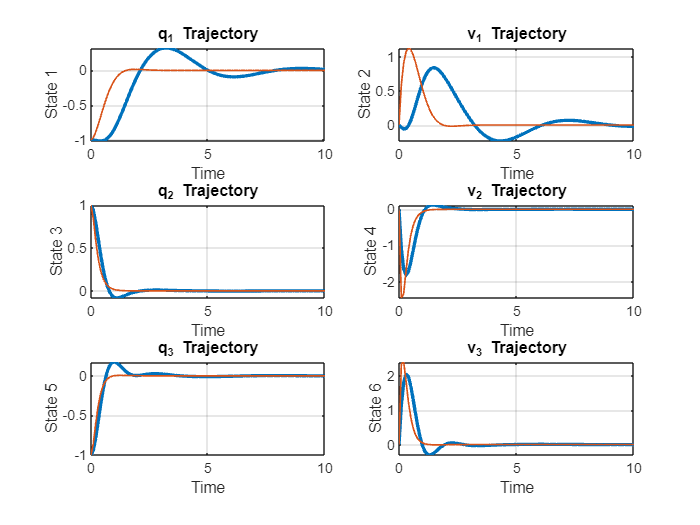


% Simulation time
t_sim = 0:0.1:10; 

% Define the system dynamics for the state-space representation
odefun_stab = @(t,x) (A + B * K_stab_CT) * x;
odefun_fast = @(t,x) (A + B * K_fast_CT) * x;
% Solve the system of ordinary differential equations (ODEs)
[t1, x_stab] = ode45(odefun_stab, t_sim, x0);
[t2, x_fast] = ode45(odefun_fast, t_sim, x0);
% Plot the state trajectories
figure
j=1;
for i = 1:6
    subplot(3, 2, i);
    plot(t1, x_stab(:, i), 'LineWidth', 2); hold on;
    plot(t2, x_fast(:, i), 'LineWidth', 1);
    if mod(i,2) == 0
        title(['v_', num2str(j), ' Trajectory']);
        j=1+j;
    else
        title(['q_', num2str(j), ' Trajectory']);
    end
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

By looking at the eigenvalues of the fast control system, it's easy to see that the controller is "overeacting" since the eigenvalues are typically far behiond the maximum value. In general, as we increase the value of alpha, the control variables increase more and more in the first instant of the motion.

This suggest that some limitations on the control action might be useful.

*DISCRETE TIME EIGENVALUES*

eig_DT=eig(F+G*K_stab_DT)

eig_DT =    0.9524 + 0.0000i
   0.9011 + 0.0357i
   0.9011 - 0.0357i
   0.6922 + 0.0557i
   0.6922 - 0.0557i
   0.6855 + 0.0000i


fast_eig_DT = max(abs(eig_DT))

fast_eig_DT = 0.9524

eig_cyrcle_DT = eig(F+G*K_cyrcle_DT)

eig_cyrcle_DT =    0.2329 + 0.0000i
   0.2404 + 0.0000i
   0.2936 + 0.0000i
   0.4862 + 0.0430i
   0.4862 - 0.0430i
   0.4907 + 0.0000i


max_eig_DT = max(abs(eig_cyrcle_DT))

max_eig_DT = 0.4907

*STATE TRAJECTORIES DISCRETE TIME*

h = 0.01

h = 0.0100

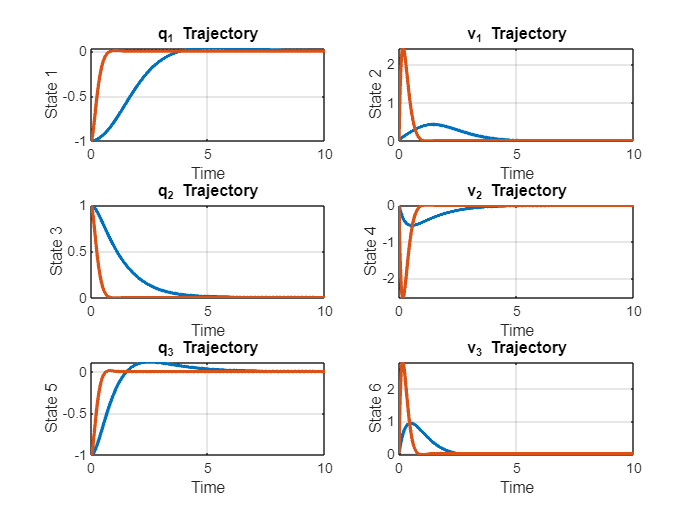

[F,G,H,L] = ssdata(c2d(ss(A,B,C,[]),h));
odefun1 = @(t, x) (F + G * K_stab_DT) * x; 
odefun2 = @(t, x) (F + G * K_cyrcle_DT) * x;

t_sim = 0:h:10;
x_stab= zeros(length(t_sim), size(F, 1));
x_stab(1, :) = x0;
for i = 2:length(t_sim)
    x_stab(i, :) = odefun1(t_sim(i), x_stab(i-1, :)');
end

x_fast = zeros(length(t_sim), size(F, 1));
x_fast(1, :) = x0;
for i = 2:length(t_sim)
    x_fast(i, :) = odefun2(t_sim(i), x_fast(i-1, :)');
end

figure
j=1;
for i = 1:6
    subplot(3, 2, i);
    plot(t_sim, x_stab(:, i), 'LineWidth', 2); hold on;
    plot(t_sim, x_fast(:, i), 'LineWidth', 2);
    if mod(i,2) == 0
        title(['v_', num2str(j), ' Trajectory']);
        j=1+j;
    else
        title(['q_', num2str(j), ' Trajectory']);
    end
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

## *Control effort*

## discrete time


 [K_effort_DT,rho_effort,feas_effort,k_L,k_Y] = LMI_DT_Effort(F,G,H,N,ContrStruct);

Constraints:
    {1×1 lmi}    {1×1 lmi}    {1×1 lmi}
    {1×1 lmi}    {1×1 lmi}    {1×1 lmi}
    {1×1 lmi}    {1×1 lmi}    {1×1 lmi}


 num. of constraints = 24
 dim. of sdp    var  = 33,   num. of sdp  blk  =  3
 dim. of socp   var  =  3,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.9e+01|1.2e+01|2.9e+04| 1.310644e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.607|0.546|2.7e+01|5.5e+00|1.8e+04| 3.647023e+02 -1.425473e+02| 0:0:00| chol  1  1 
 2|0.770|0.735|6.2e+00|1.5e+00|6.3e+03| 3.217676e+02 -2.784590e+02| 0:0:00| chol  1  1 
 3|0.603|0.668|2.5e+00|5.2e-01|3.1e+03| 4.906643e+02 -2.7464

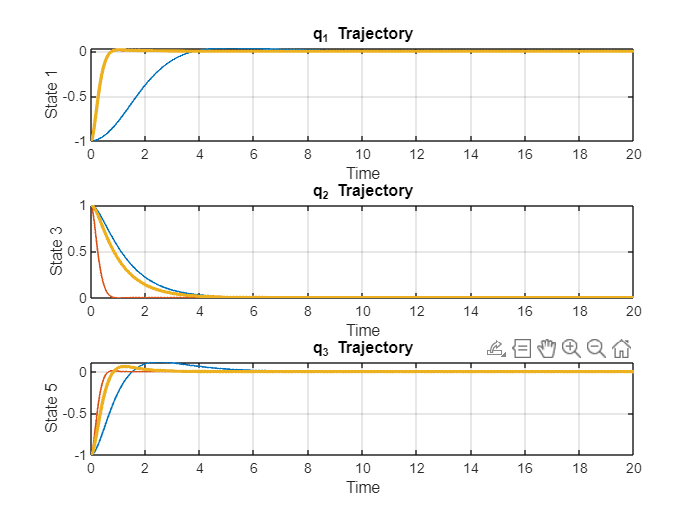

j = 2

j = 3

j = 4

odefun3 = @(t, x) (F + G * K_effort_DT) * x;
odefun1 = @(t, x) (F + G * K_stab_DT) * x;
odefun2 = @(t, x) (F + G * K_cyrcle_DT) * x;

t_sim = 0:h:20;
x_effort= zeros(length(t_sim), size(F, 1));
x_effort(1, :) = x0;
x_stab= zeros(length(t_sim), size(F, 1));
x_stab(1, :) = x0;
x_fast = zeros(length(t_sim), size(F, 1));
x_fast(1, :) = x0;
for i = 2:length(t_sim)
    x_effort(i, :) = odefun3(t_sim(i), x_effort(i-1, :)');
    x_stab(i, :) = odefun1(t_sim(i), x_stab(i-1, :)');
    x_fast(i, :) = odefun2(t_sim(i), x_fast(i-1, :)');
end

figure
j=1;
for i = 1:2:5
    subplot(3, 1, j);
    plot(t_sim, x_stab(:, i), 'LineWidth', 1); hold on;
    plot(t_sim, x_fast(:, i), 'LineWidth', 1);
    plot(t_sim, x_effort(:, i), 'LineWidth', 2);
    j = j+1
        title(['q_', num2str(j-1), ' Trajectory']);
    
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

## Continous time

[K_effort_CT,rho_effort_CT,feas_effort_CT] = LMI_CT_Effort(A,B,C,N,ContrStruct);

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 24, order n = 36, dim = 301, blocks = 6
nnz(A) = 81 + 0, nnz(ADA) = 488, nnz(L) = 256
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.03E+00 0.000
  1 :  -1.51E+01 1.49E+00 0.000 0.2474 0.9000 0.9000   1.17  1  1  3.6E+00
  2 :  -2.00E+01 5.26E-01 0.000 0.3523 0.9000 0.9000   0.95  1  1  1.4E+00
  3 :  -2.60E+01 1.58E-01 0.000 0.3009 0.9000 0.9000   0.54  1  1  5.4E-01
  4 :  -2.48E+01 4.92E-02 0.000 0.3110 0.9000 0.9000   0.68  1  1  2.0E-01
  5 :  -2.22E+01 1.71E-02 0.000 0.3479 0.9000 0.9000   0.68  1  1  8.1E-02
  6 :  -2.04E+01 7.33E-03 0.000 0.4282 0.9000 0.9000   0.61  1  1  4.0E-02
  7 :  -1.95E+01 3.23E-03 0.000 0.4415 0.9000 0.9000   0.66  1  1  2.1E-02
  8 :  -1.87E+01 1.29E-03 0.000 0.3978 0.9000 0.9000   0.63  1  1  9.9E-03
  9 :  -1.83E+01 5.22E-04 0.000 0.4060 0.9000 0.9000   0.75  1  1  4.4E-03
 10 :  -1.81E

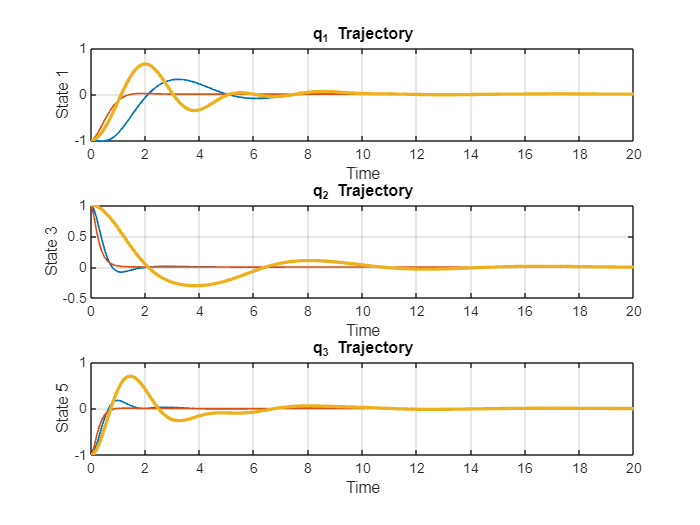

j = 2

j = 3

j = 4

% Simulation time
t_sim = 0:0.1:20; 

% Define the system dynamics for the state-space representation
odefun_stab = @(t,x) (A + B * K_stab_CT) * x;
odefun_fast = @(t,x) (A + B * K_fast_CT) * x;
odefun_effort = @(t,x) (A + B * K_effort_CT) * x;
% Solve the system of ordinary differential equations (ODEs)
[t1, x_stab] = ode45(odefun_stab, t_sim, x0);
[t2, x_fast] = ode45(odefun_fast, t_sim, x0);
[t3, x_effort] = ode45(odefun_effort, t_sim, x0);
% Plot the state trajectories
figure
j=1;
for i = 1:2:5
    subplot(3, 1, j);
    plot(t1, x_stab(:, i), 'LineWidth', 1); hold on;
    plot(t2, x_fast(:, i), 'LineWidth', 1);
    plot(t2, x_effort(:, i), 'LineWidth', 2);
    j = j+1
        title(['q_', num2str(j-1), ' Trajectory']);
    
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

## *H2 control *

## Continous time

[K_H2_CT,rho_H2_CT,feas_H2_CT] = LMI_CT_H2(A,B,C,N,ContrStruct);


 num. of constraints = 66
 dim. of sdp    var  = 27,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.3e+01|1.5e+01|3.7e+03|-7.569000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.763|0.739|7.9e+00|4.1e+00|1.0e+03|-7.880061e+01 -7.280988e+01| 0:0:00| chol  1  1 
 2|0.649|0.594|2.8e+00|1.7e+00|5.2e+02|-1.161166e+02 -1.286281e+02| 0:0:00| chol  1  1 
 3|0.319|0.497|1.9e+00|8.3e-01|3.9e+02|-1.838773e+02 -1.750173e+02| 0:0:00| chol  1  1 
 4|0.489|1.000|9.7e-01|1.0e-04|3.3e+02|-2.132912e+02 -3.392712e+02| 0:0:00| chol  1  1 
 5|0.971|0.863|2.8e-02|2.2e-05|4.3e+01|-1.850087e+02 -2.242948e+02| 0:

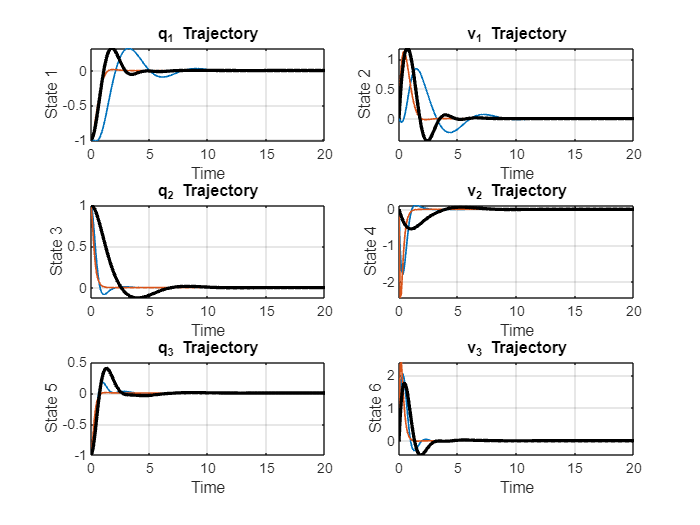


% Simulation time
t_sim = 0:0.1:20; 

% Define the system dynamics for the state-space representation
odefun_stab = @(t,x) (A + B * K_stab_CT) * x;
odefun_fast = @(t,x) (A + B * K_fast_CT) * x;
odefun_H2 = @(t,x) (A + B * K_H2_CT) * x;
% Solve the system of ordinary differential equations (ODEs)
[t1, x_stab] = ode45(odefun_stab, t_sim, x0);
[t2, x_fast] = ode45(odefun_fast, t_sim, x0);
[t3, x_H2] = ode45(odefun_H2, t_sim, x0);
% Plot the state trajectories
figure
j=1;
for i = 1:6
    subplot(3, 2, i);
    plot(t1, x_stab(:, i), 'LineWidth', 1); hold on;
    plot(t2, x_fast(:, i), 'LineWidth', 1);
    plot(t3, x_H2(:, i), 'LineWidth', 2, 'Color',"black");
    if mod(i,2) == 0
        title(['v_', num2str(j), ' Trajectory']);
        j=1+j;
    else
        title(['q_', num2str(j), ' Trajectory']);
    end
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

## Discrete time

[K_H2_DT,rho_H2_DT,feas_H2_DT] = LMI_DT_H2(F,G,H,N,ContrStruct);


 num. of constraints = 66
 dim. of sdp    var  = 27,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+01|3.9e+01|5.1e+03|-3.105000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.836|0.929|4.3e+00|2.9e+00|7.3e+02|-2.016327e+01 -9.680839e+01| 0:0:00| chol  1  1 
 2|0.867|0.575|5.7e-01|1.2e+00|2.3e+02|-3.146869e+01 -9.479411e+01| 0:0:00| chol  1  1 
 3|0.828|0.535|9.8e-02|5.7e-01|1.2e+02|-7.626792e+01 -7.658647e+01| 0:0:00| chol  1  1 
 4|0.240|0.228|7.4e-02|4.4e-01|1.2e+02|-2.200669e+02 -7.956348e+01| 0:0:00| chol  1  1 
 5|0.078|0.064|6.8e-02|4.1e-01|1.6e+02|-7.515494e+02 -9.552158e+01| 0:

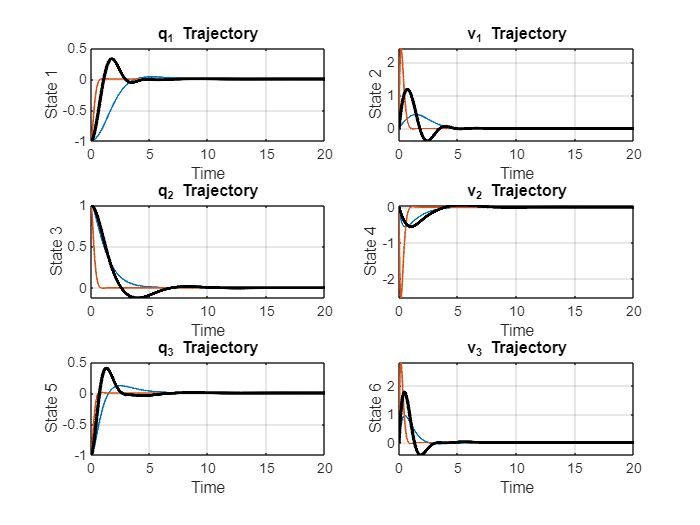

% Simulation time
t_sim = 0:0.1:20; 

odefun3 = @(t, x) (F + G * K_H2_DT) * x;
odefun1 = @(t, x) (F + G * K_stab_DT) * x;
odefun2 = @(t, x) (F + G * K_cyrcle_DT) * x;

t_sim = 0:h:20;
x_H2= zeros(length(t_sim), size(F, 1));
x_H2(1, :) = x0;
x_stab= zeros(length(t_sim), size(F, 1));
x_stab(1, :) = x0;
x_fast = zeros(length(t_sim), size(F, 1));
x_fast(1, :) = x0;
for i = 2:length(t_sim)
    x_H2(i, :) = odefun3(t_sim(i), x_H2(i-1, :)');
    x_stab(i, :) = odefun1(t_sim(i), x_stab(i-1, :)');
    x_fast(i, :) = odefun2(t_sim(i), x_fast(i-1, :)');
end

figure
j=1;
for i = 1:6
    subplot(3, 2, i);
    plot(t_sim, x_stab(:, i), 'LineWidth', 1); hold on;
    plot(t_sim, x_fast(:, i), 'LineWidth', 1);
    plot(t_sim, x_H2(:, i), 'LineWidth', 2,'Color',"black");
    if mod(i,2) == 0
        title(['v_', num2str(j), ' Trajectory']);
        j=1+j;
    else
        title(['q_', num2str(j), ' Trajectory']);
    end
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end